# EE4530 Applied Convex Optimization mini-Project - SVM

## Clear all

clear all;
clc;
close all;

## 1. Data Load

load("linear_svm.mat");

### Data Exploration

Take a look to the data

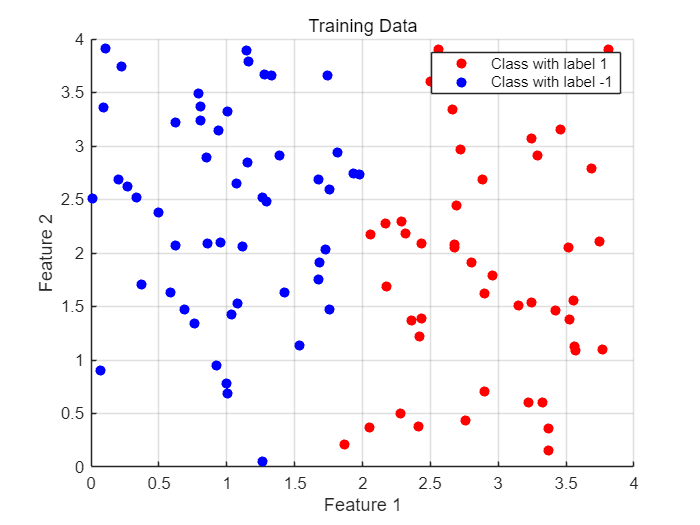

% plot the training data
figure;

% plot data with label = 1
scatter(X_train(labels_train == 1, 1), X_train(labels_train == 1, 2), 'ro', 'filled');
hold on;

% plot data with label = -1
scatter(X_train(labels_train == -1, 1), X_train(labels_train == -1, 2), 'bo', 'filled');

title('Training Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
% axis padded;
hold off;

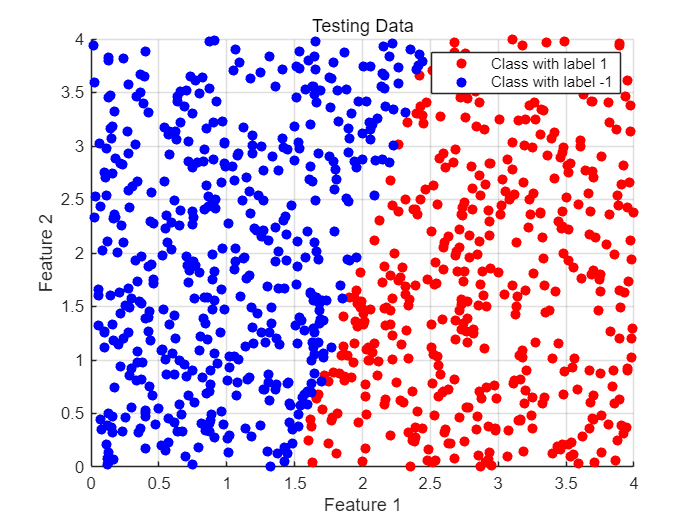

% plot the testing data
figure;

% plot data with label=1
scatter(X_test(labels_test == 1, 1), X_test(labels_test == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X_test(labels_test == -1, 1), X_test(labels_test == -1, 2), 'bo', 'filled');

title('Testing Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
hold off;

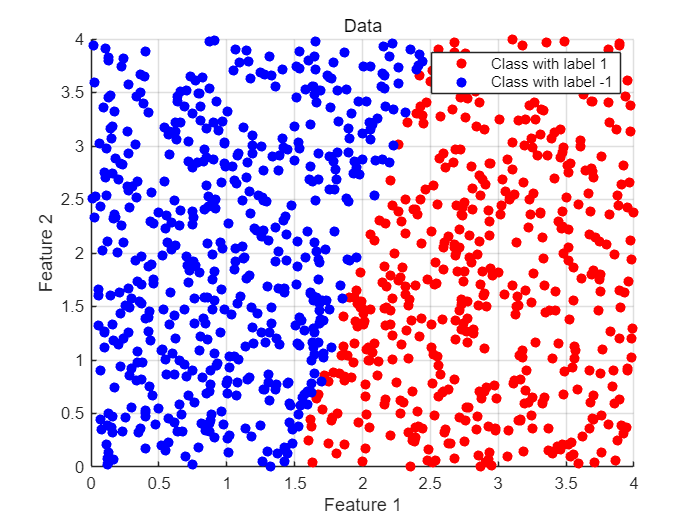

% plot the hole data
figure;

% get the whole data
X = [X_test; X_train];
labels = [labels_test; labels_train];

% plot data with label=1
scatter(X(labels == 1, 1), X(labels == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X(labels == -1, 1), X(labels == -1, 2), 'bo', 'filled');

title('Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
hold off;

% 分出两组数据点
X_red = X(labels == 1, :);
X_blue = X(labels == -1, :);

% 计算每组数据的凸包
k1 = convhull(X_red(:,1), X_red(:,2));
k2 = convhull(X_blue(:,1), X_blue(:,2));

% 获取凸包的顶点
hull1 = X_red(k1, :);
hull2 = X_blue(k2, :);

% 判断两个凸包是否有交集
% 使用 polyshape 和 overlaps 函数
poly1 = polyshape(hull1);
poly2 = polyshape(hull2);

% 检查是否重叠
isOverlap = overlaps(poly1, poly2);

if isOverlap
    disp('不可分');
else
    disp('可分');
end

可分


## 1.Task 1

硬约束: svm最优化目标为最大化决策边界, 转化为下面的公式


$$\min_{\vec{w}} f(\vec{w})=\frac{||\vec{w}||^2}{2} \\
\text{s.t.}  \ g_i(\vec{w}, b) = y_i \cdot(\vec{w}\cdot \vec{x_i} + b) \geq 1

$$


[N_train, n] = size(X_train);
[N_test, n] = size(X_test);

tic;        % 运算时长
% Convex计算
cvx_begin
    variables w(n) b;
    % 目标
    minimize(0.5 * w' * w);

    % 约束条件
    subject to
        for i = 1:N_train
            labels_train(i) * (X_train(i, :) * w + b) >= 1;
        end
cvx_end

 
Calling SDPT3 4.0: 104 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  1
 dim. of linear var  = 100
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+02|2.4e+01|5.0e+04|-2.000000e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.410|0.416|5.7e+02|1.4e+01|4.0e+04|-1.397413e+03 -7.987107e+01| 0:0:00| chol  1  1 
 2|0.300|0.326|4.0e+02|9.3e+00|3.5e+04|-9.280953e+02 -2.648473e+02| 0:0:00| chol  1  1 
 3|0.202|0.255|3.2e+02|7.0e+00|3.3e+

time = toc;

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (11.255635, -1.973901)'
Optimal b: -17.888523
Running time: 1.463760

y_pre = svm_predict(w, b, X_test);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.976667

## 2. Task 2

% data preprocessing
X_train_normalized = normalize(normalize(X_train), "range");
X_test_normalized = normalize(normalize(X_test), "range");

% 超参数
lambda = 0.01;
t = 0.01;
num_iters = 1000;

% 训练 SVM
tic;
[w, b] = svm_gd(X_train_normalized, labels_train, lambda, t, num_iters);
time = toc;

% 显示结果
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (2.044021, -0.820165)'
Optimal b: -0.550000
Running time: 0.008951

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.942222

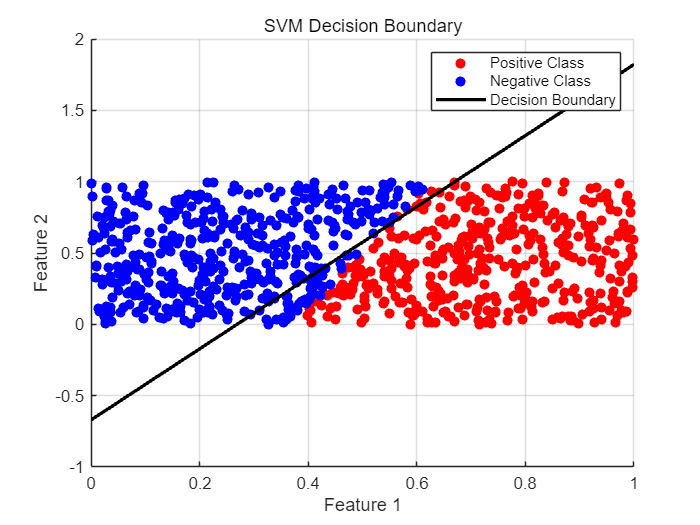

plot_svm_decision_boundary(X_test_normalized, labels_test, w, b);

% 超参数
% num_iters = 1000;
alpha = 0.25;
beta = 0.5;
t0 = 0.01;

% 训练 SVM
tic;
[w, b, iter] = svm_bls(X_train_normalized, labels_train, lambda, num_iters, alpha, beta, t0);
time = toc;

% 显示结果
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nNumber of iteration: %d", ...
    w(1), w(2), b, time, iter);

Optimal w: (5.170825, -0.585432)'
Optimal b: -2.328125
Running time: 0.009054
Number of iteration: 13

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.955556

    5.1700
   -0.5900

   -2.3300

    5.1694
   -0.6066

   -2.4046



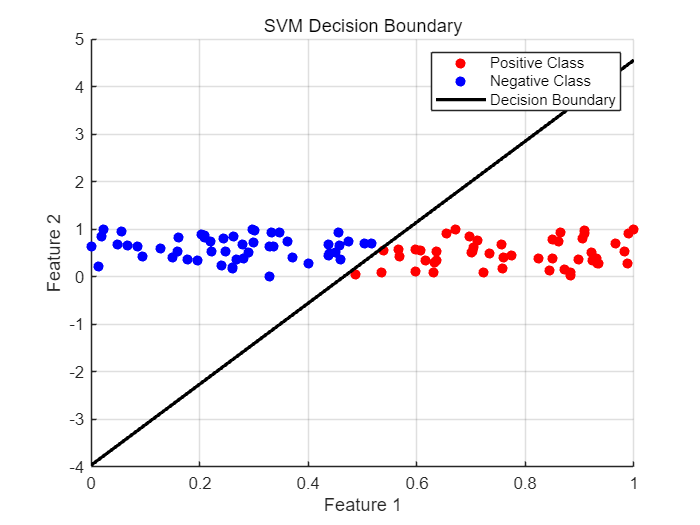

------------
    5.1694
   -0.6066

   -2.4046

    5.7957
    0.5114

   -1.2060



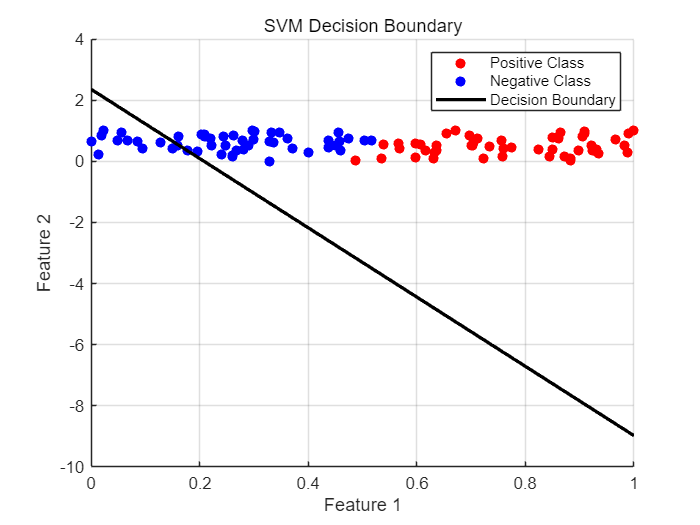

------------
    5.7957
    0.5114

   -1.2060

    4.9261
    2.4953

    4.2815



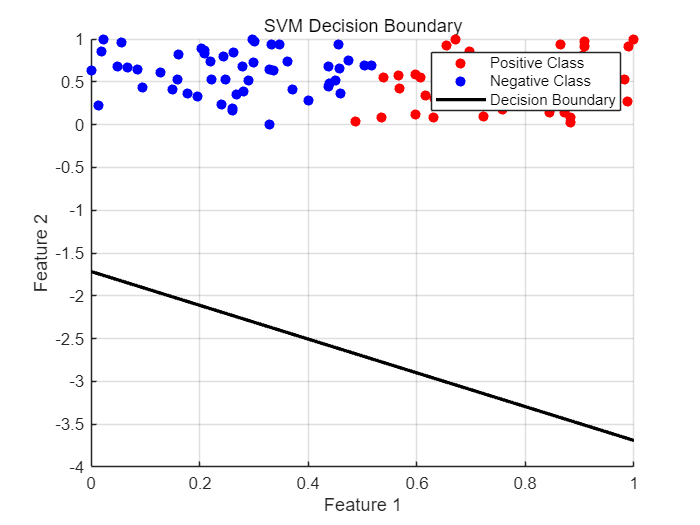

------------
    4.9261
    2.4953

    4.2815

    2.8177
    1.9922

    7.6103



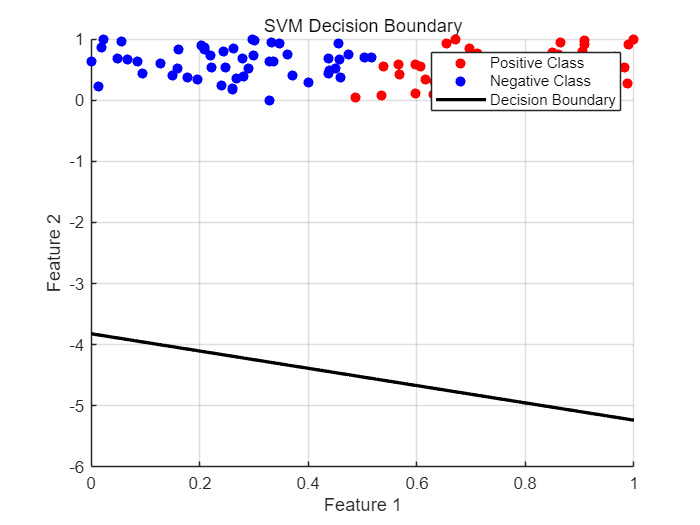

------------
    2.8177
    1.9922

    7.6103

    1.3388
    1.1833

   10.3980



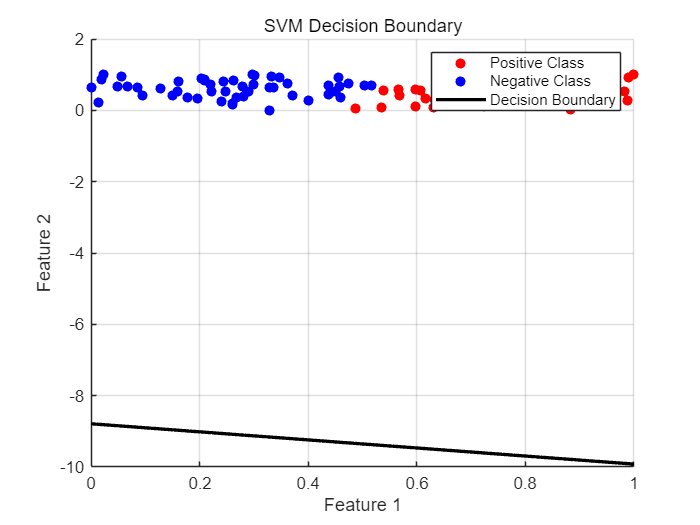

------------
    1.3388
    1.1833

   10.3980

    0.6200
    0.6179

   12.8109



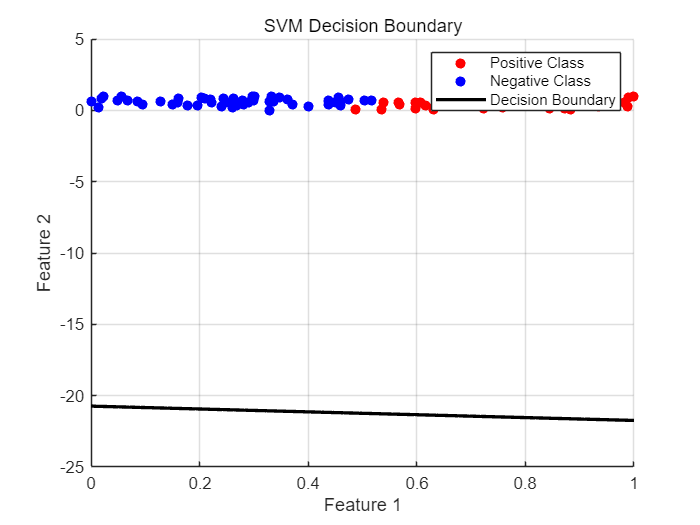

------------
    0.6200
    0.6179

   12.8109

    0.3238
    0.3330

   14.9185



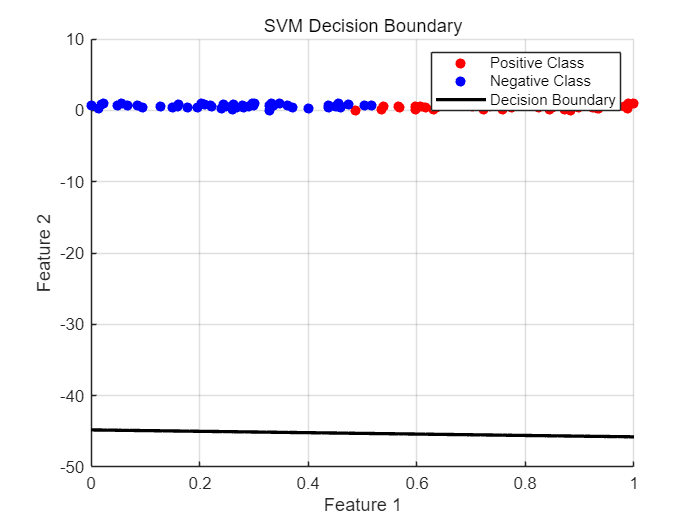

------------


% 超参数
num_iters = 30;
t = 1; % 初始障碍参数
mu = 1.5; % 增加 t 的倍数
tol = 10; % 收敛容忍度
step_size = 1e-2;

% 训练 SVM
tic;
[w, b, iter, w_res, b_res] = svm_barrier(X_train_normalized, labels_train, t, mu, tol, num_iters, step_size);

time = toc;

% 显示结果
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nNumber of iteration: %d", ...
    w(1), w(2), b, time, iter);

Optimal w: (0.323765, 0.332998)'
Optimal b: 14.918453
Running time: 0.575086
Number of iteration: 210

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.475556

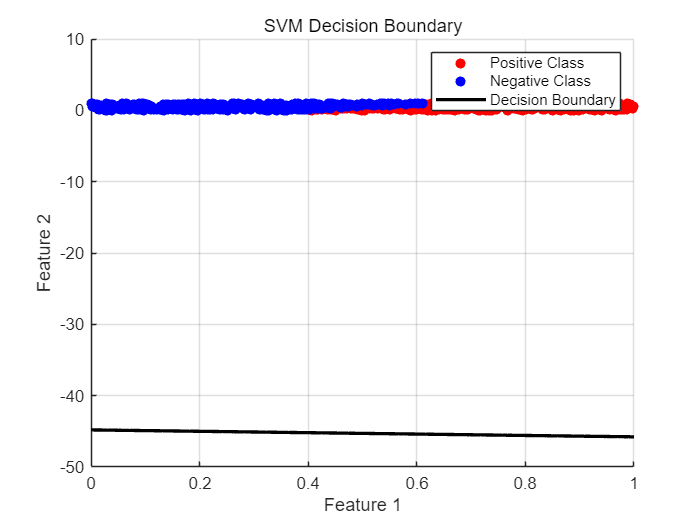

plot_svm_decision_boundary(X_test_normalized, labels_test, w, b);

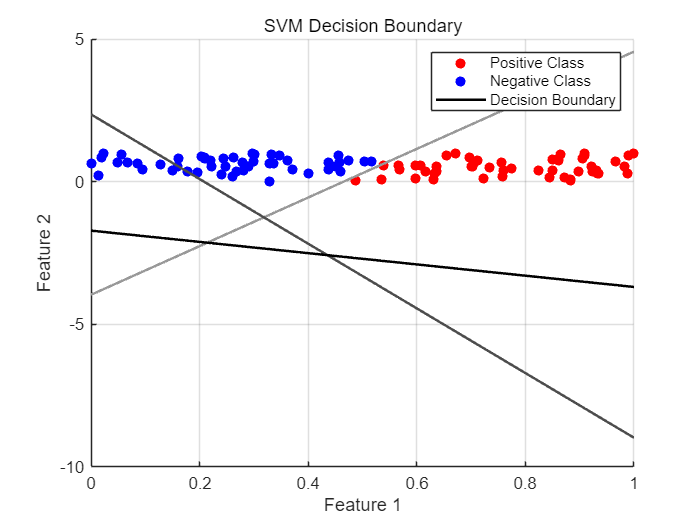

% plot the changing of the hyperplain
figure;
hold on;
pos = find(labels_train == 1);
neg = find(labels_train == -1);
scatter(X_train_normalized(pos, 1), X_train_normalized(pos, 2), 'ro', 'filled'); % 正类
scatter(X_train_normalized(neg, 1), X_train_normalized(neg, 2), 'bo', 'filled'); % 负类

% 绘制决策边界 wx + b = 0
x_min = min(X_train_normalized(:, 1));
x_max = max(X_train_normalized(:, 1));
x_plot = linspace(x_min, x_max, 100);
color = [0.6, 0.6, 0.6];
for i = 1:3
    y_plot = -(w_res(i, 1) * x_plot + b_res(i)) / w_res(i, 2);
    if i ~= 3
        line = plot(x_plot, y_plot, 'k-', 'LineWidth', 1.5, 'Color', color,...
            'HandleVisibility', 'off'); % 决策边界
    else
        line = plot(x_plot, y_plot, 'k-', 'LineWidth', 1.5, 'Color', color); % 决策边界
    end
    color = color - [0.3, 0.3, 0.3];
end

% 设置图形参数
% breakyaxis([-120 -110, -6 6]);
xlabel('Feature 1');
ylabel('Feature 2');
title('SVM Decision Boundary');
legend('Positive Class', 'Negative Class', 'Decision Boundary');
grid on;
hold off;